Sam Kramer 

Dr. Alfred Wicks

ME 5714: Digital Signal Processing

## Assignment 8 -- Inverse FFT

%{
    This will be a script that will be used to complete Assignment 8 
    for ME 5714 -- Digital Signal Processing.

    Sam Kramer
    March 23rd, 2023
%}

### Problem Statement

Matlab has an inverse transform function. Using the 90 sample data vector created from the dimmer problem in the mid-term, You’ll have to create it. Obtain the fft of the data vector, show the plot.

As in the exam, take the inverse transform using only the first 20 spectral components.You can accomplish this by zeroing the other components.

Compare the result with what you found in the mid term and the original function.

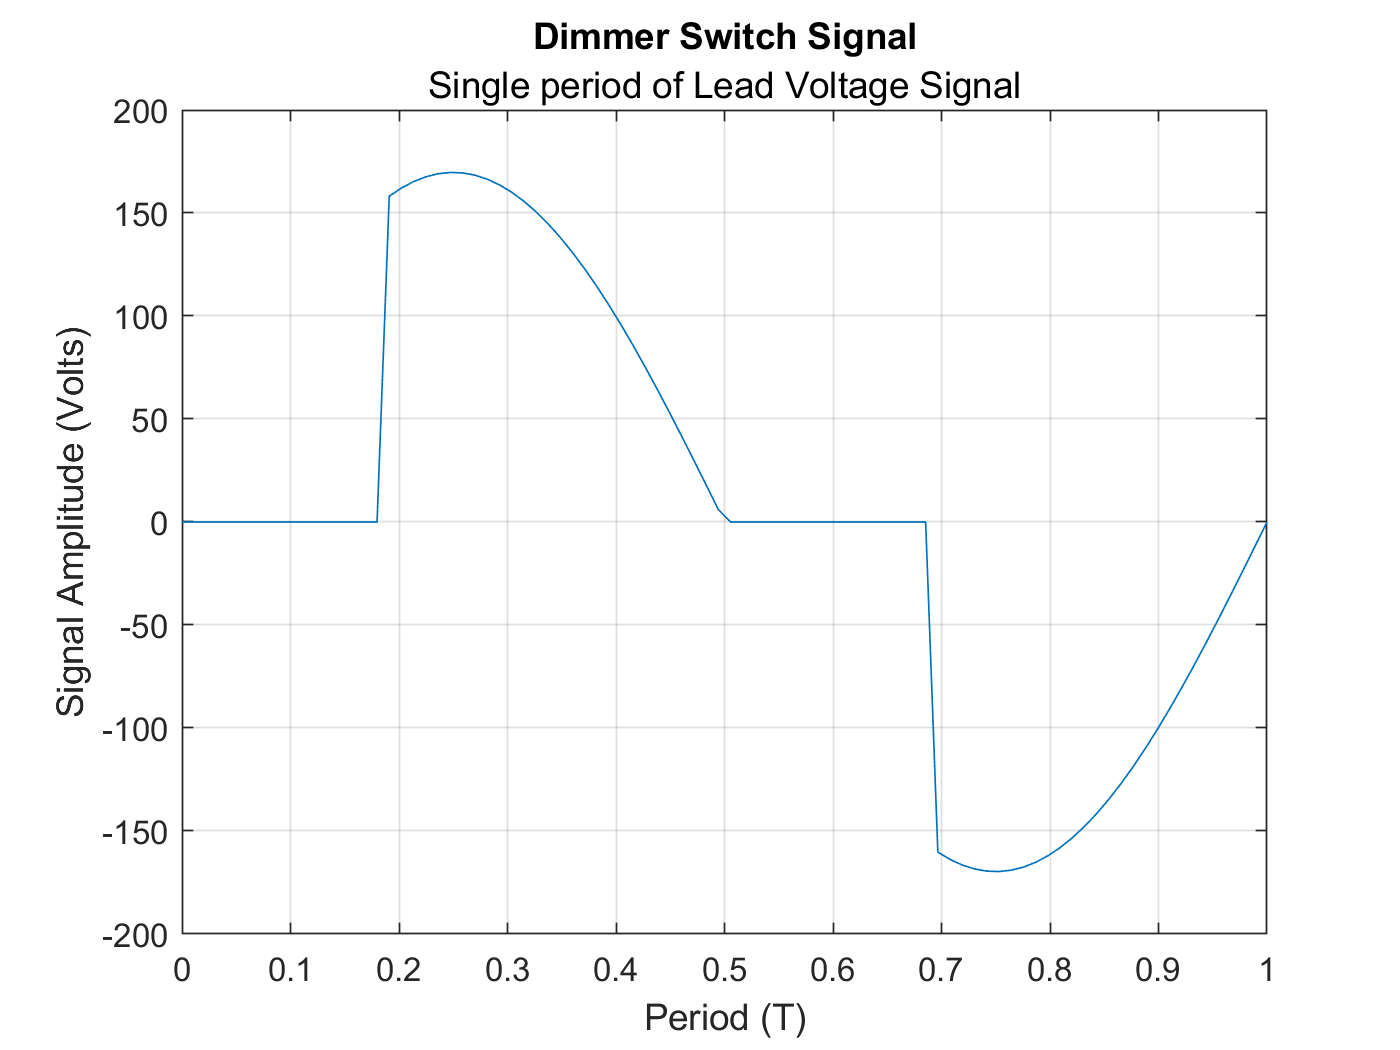

% --Script setup
    clear; clc; close all; format compact;

% --Wave parameters
    fs = 20;                        % Sample frequency (samples/cycle)
    ac_freq = 60;                   % AC signal frequency (Hz)
    w0 = 2 * pi * ac_freq;          % Signal frequency (rad/s)
    ac_amp_rms = 120;               % RMS AC Amplitude (Volts)
    ac_amp = sqrt(2) * ac_amp_rms;  % Signal Peak amplitude (V)
    leng = 90;                      % Length of vectors
    wave = zeros(1,leng);           % Wave solution vector
    sig_T = 1/ac_freq;              % Period of one cycle
    time = linspace(0,sig_T, leng); % Time vector for signal wave
    
% --Original Sine Wave generation
    sine_wave = ac_amp*sin(w0*time);
    T = leng;                       % Length of one cycle
    switch1 = round(7*T/36);        % Switch on at 70deg phase
    switch2 = round(25*T/36);       % Switch on a 250deg phase
    
% --Construction of Wave
    wave(switch1:T/2) = sine_wave(switch1 : T/2);
    wave(switch2:T) = sine_wave(switch2 : T);
    
% --Plot signal wave
    figure(1)
    period360 = time./max(time);
    plot(period360,wave)
        hold on 
        grid on
        subtitle('Raw AC Signal input')
        title('Dimmer Switch Signal')
        xlabel('Period (T)')
        ylabel('Signal Amplitude (Volts)')
        subtitle('Single period of Lead Voltage Signal')

## Finding DFT of Signal

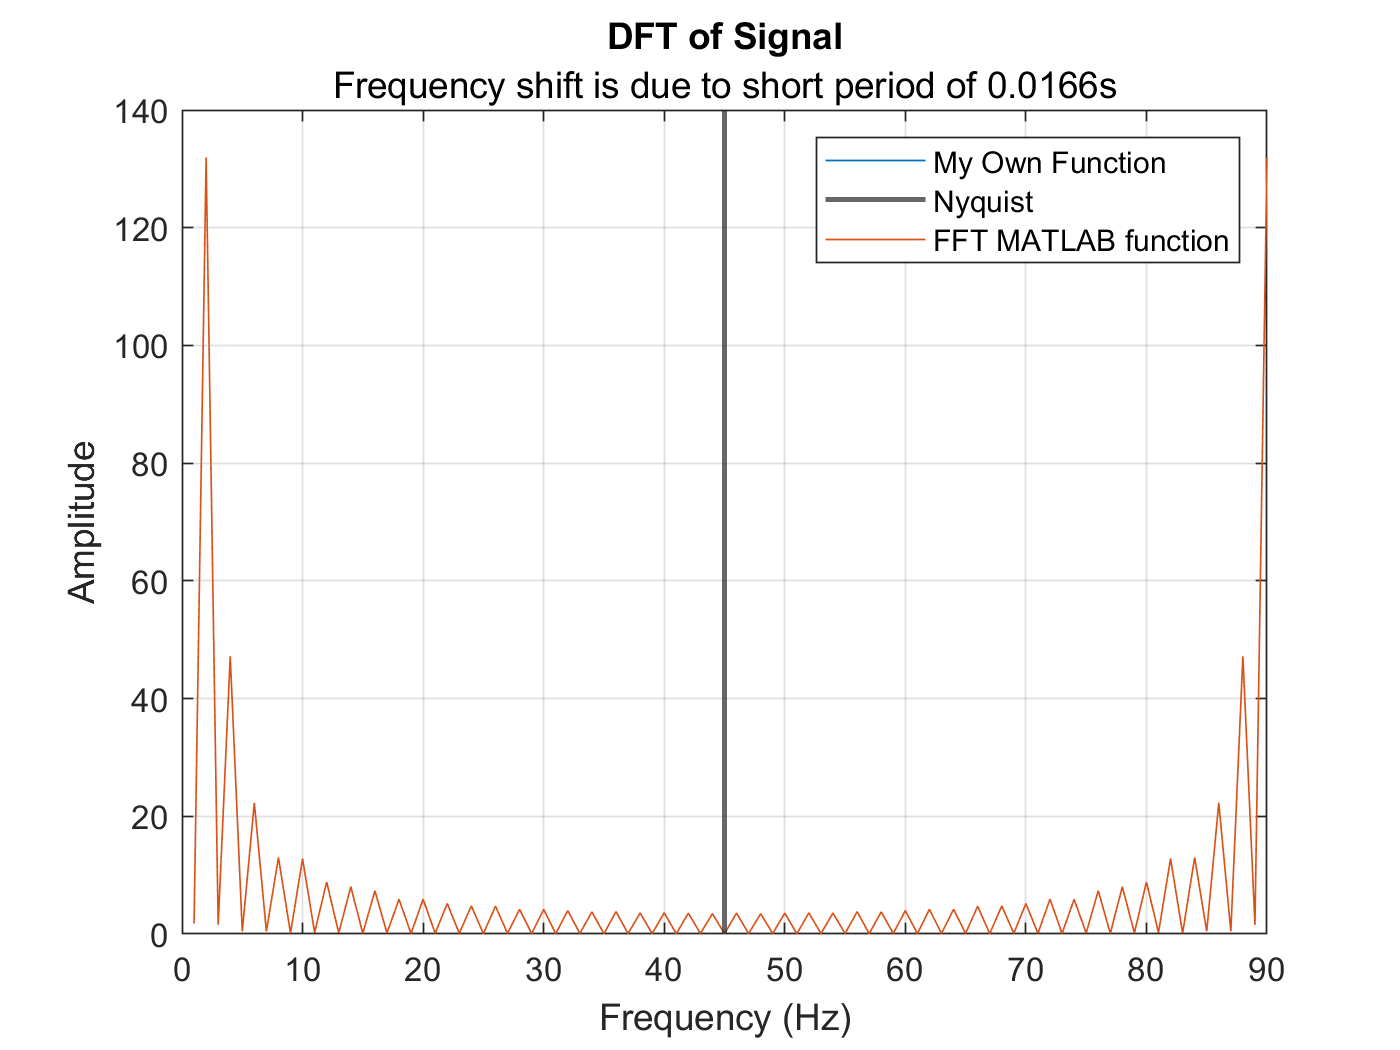

% --Setup of DFT of Signal
    N = length(wave);                       % Samples of the signal
    sol_amplitude = [];                     % Solution amplitude vector
    n = 0:N - 1;                            % Temporal Index of system
    Cn = [];                                % Cn vectors
    
    
% --Perform DFT of Signal
    for m = 0:N-1               % Frequency index
        
        % --First exponent term
            C = (exp((-1i*2*pi*m*n)/N))';
            
        % --Complete Cm calculation and calculate amplitude
            magnitude = sum(wave * C);
            Cn = [Cn magnitude];
            amplitude = 2*abs(magnitude)/N;
        
        % --Save values
            sol_amplitude = [sol_amplitude, amplitude];
        
    end

% --Format frequency vectors
    freq = 1:N;
    
% --Using the FFT function
    fftdata = fft(wave);
    fftdata2 = 2*abs(fftdata)/N;
    
% --Plot DFT
    figure(2)
    plot(freq, sol_amplitude)
        hold on
        grid on
        xline(max(freq)/2,'LineWidth',1.5)
        xlabel('Frequency (Hz)')
        ylabel('Amplitude')
        title('DFT of Signal')
        subtitle('Frequency shift is due to short period of 0.0166s')
    plot(fftdata2)
        legend('My Own Function','Nyquist','FFT MATLAB function')

## Taking Inverse FFT of Data

% --Take first 20 data points
    data_points = 20;
    zero_add = zeros(1,length(Cn) - data_points);
    Cn(21:end) = zero_add;
    
% --Setup ifft of data
    N = length(Cn);          % Length of data set   
    xt = [];                            % Final signal
    n = 1:N;                          % Temporal index
    period = n/N; 
    
% --Inverse fft in a for loop
    for k = 0:N - 1
        
        % --Calculation of first term (Transposed)
            W = (exp((1i*2*pi*k*n)/N))';
            
        % --Summation term using dot product 
            XN = sum(Cn * W);
            
        % --Normalizing and getting into cartesian coords
            YT = sign(real(XN))*abs(XN)/N;
            
        % --Store values to plot
            xt = [xt YT];  
        
    end

% --Reformat xt values to be in terms of period
    ft = xt(1:length(period));
    
% --ifft of data
    ft2 = ifft(Cn);
    
% --Plot data
    figure(3)
    plot(period360,ft)
        hold on
        grid on
        xlabel('Period (T)')
        ylabel('Amplitude (Volts)')
        title('Recreation of Dimmer Switch Signal using first 20 Data Points')
        
    plot(period,ft2)

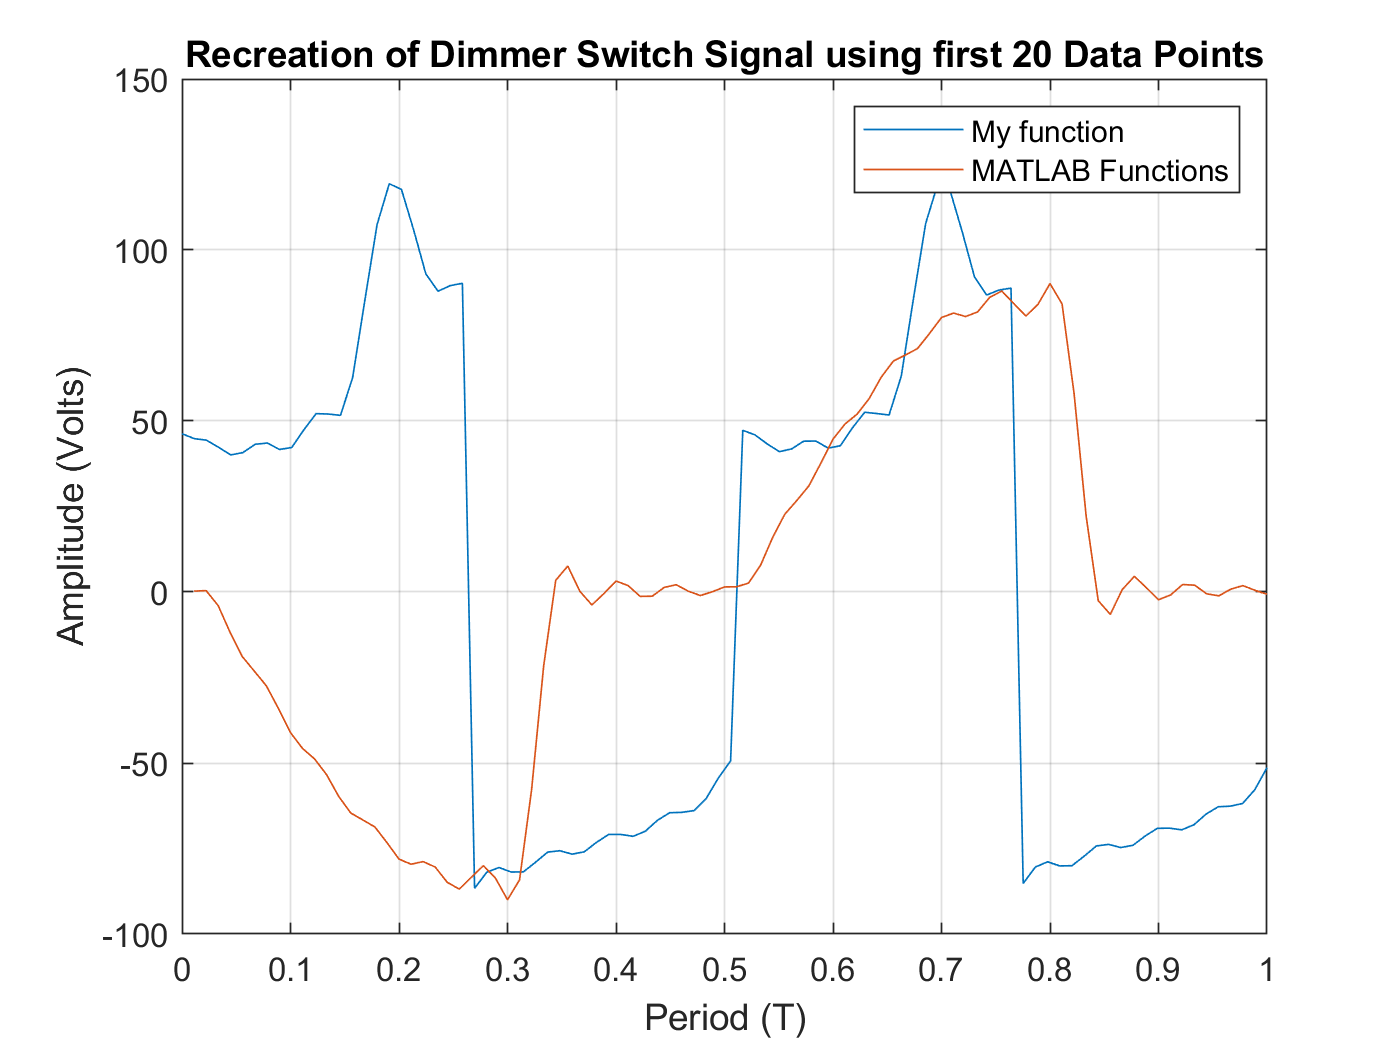

    legend('My function','MATLAB Functions')

## Analysis of Signal

    When taking the FFT of the signal that was constructed with 90 data points, the proper method to find the resolution of frequency spectrum of the signal we must take a frequency index step of 1/T. However, with this method we are doing that with a period (T) of 0.0166 seconds and so this yeilds over 8,000 data points and a very high resolution. Also, beause our period is small, our frequency spectrum is shifted and so the spikes appear at values much lower to their actual location. This is due to one of the assumptions that we made to not normalize by T and to have a very small period for one signal cycle. However, that doesn't matter if we are to take the inverse fourier transform because the signal will be reconstructed in the proper way.

    For my work above I was not able to do an inverse fourier transform of a vector with a frequency index of 1/T because of the amount of FLOPs required was too much for my computer to do quickly so I used a frequency index step of 1 from 0 to N-1 samples. This constructed the signal to a good degree of accuracy. The last value is also clipped out becuase the of the N-1 frequency sweep that was done during the DFT of the signal. This is actually the same method that the MATLAB fft and ifft functions use. 